clear; close all;

# Solve Poisson Equation

Consider the 2D Poisson equation with only Dirichlet boundary conditions:


$$u_t-\Delta u = f\quad \text{on }\Omega\\
u=g\quad\text{on }\partial\Omega\\
u=u_0\quad t=0$$


where


$$g=sin\left(x\right)cos\left(y\right)cos\left(t\right)\ldotp$$


and


$$f=sin\left(x\right)cos\left(y\right)\left(−sin\left(t\right)+2cos\left(t\right)\right)\ldotp$$


global f g
f = @(x,y,t) sin(x).*cos(y).*(-sin(t)+2*cos(t));
g = @(x,y,t) sin(x).*cos(y).*cos(t);

Note that one true solution is $u=g$ if $u_0(x,y)=g(x, y, 0)$.

u_true = g;

## Domain

First we define our domain $\Omega$ and generate a function space on it with finite element of choice:

addpath('..')
import MatFem.*
domain = [-0.4 0.4 -0.4 0.4]; % define a domain with -0.4 ≤ x ≤ 0.4, -0.4 ≤ y ≤ 0.4
% NOTE: if we choose too large a mesh, each mesh grid will have little communication, which lead
% to poor observability.
shape  = [8 8];        % 8 x 8 grids
mesh   = rectMesh(domain, shape);

Now let's construct a degree 2 function space with 9 quadrature points in each element:

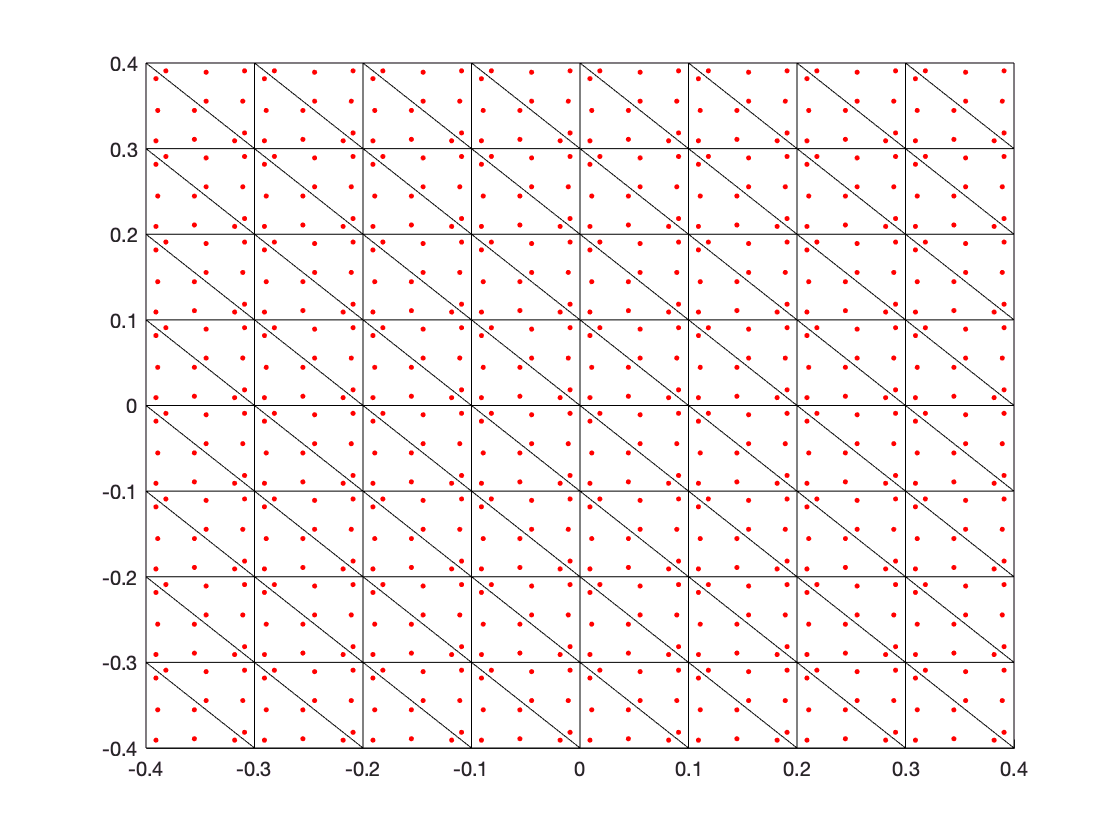

global V
V = MatFem.mesh2spc(mesh, 1, 4); % P1 element with degree 4 quadrature
figure()
V.plot()

% title('Function space of degree 2 element and degree 4 quadrature points')

## Variational form

With backward-Euler, the variational form at time $t$ is


$$\int_\Omega( u_tv+\Delta t\nabla u_t\cdot\nabla v)=\int_\Omega (\Delta t\,fv+u_{t-\Delta t}v).$$


The left hand side matrix then can be assembled as

import MatFem.assemble
global dt A Auv

dt = 0.001; % Choose a ∆t
Auv = assemble(V, [0 0; 0 0]); % the [0 0; 0 0] are derivative orders of 
                               % u (first row) and v (second row)
                               % wrt x (first column) and y (second column).
                               % So this term is integrate(u*v)
A = Auv + dt * assemble(V, [1 0; 1 0]); % ∆t * integrate(u_x*v_x)
A = A   + dt * assemble(V, [0 1; 0 1]); % ∆t * integrate(u_y*v_y)

To see what `assemble` does, run

% help assemble

## Boundary Condition

Boundary conditions can be defined as

global bc
bc = MatFem.rectBndCond(V, 'd', domain); % 'd' means dirichlet. This creates Dirichlet boundary conditions on all four edges of our domain.
[~, A] = bc.applyDir('d', 0, [], A);     % apply Dirichlet boundary conditions to A. The value at boundary is not important here.

## Solution

Now let us solve the system.

We'd like to write a function $F$s.t. $u_t=F(u_{t-\Delta t}, t)$.

Definition code is placed at the end of the file.

Now let's examine the solution. Given initial value $u_0=g(t=0)$, our solution should be close to $g$.

T = 1;

u = V.project(@(x,y)u_true(x,y,0)); % initial condition
for t = dt:dt:T
    u = F(u, t); % solve for next state
end
MatFem.errorNorm(V, u, @(x,y)u_true(x,y,T), 'L2')

ans = 1.9745e-04

A more rigorous test would be to examin convergence rate. But it is not our focus here.

# Data Assimilation

Suppose we are trying to recover the initial state $u_0=g(t=0)$.

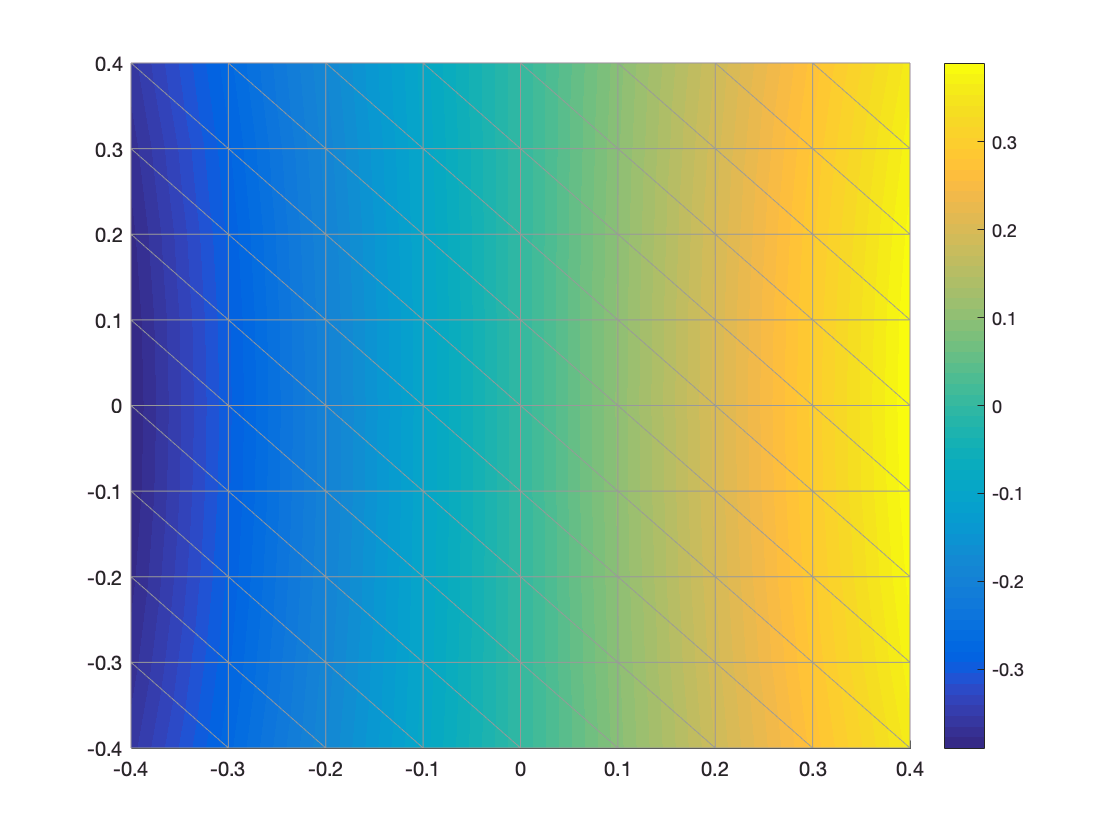

V.plotu(@(x,y)u_true(x,y,0))

## Bases

The number of bases in our function space $V$

V.nb

ans = 81

However the Dirichlet boundaries reduces some of them. In order to find all valid bases, we can apply Dirichlet Boundary conditions

global bases
bases = ones(V.nb, 1);
bases = bc.applyDir('d', 0, bases);
bases = logical(bases);

Now the number of bases is

nb = sum(bases)

nb = 49

We can write a function to map a vector $[\alpha_1, \alpha_2, \ldots, \alpha_{nb}]$ to a function in our function space $V$ with value 0 at all Dirichlet boundaries. See the function `alphas2V` at the end of this file. And the function `V2alphas` is vice versa.

Now the $i^{\rm th}$ base function is:

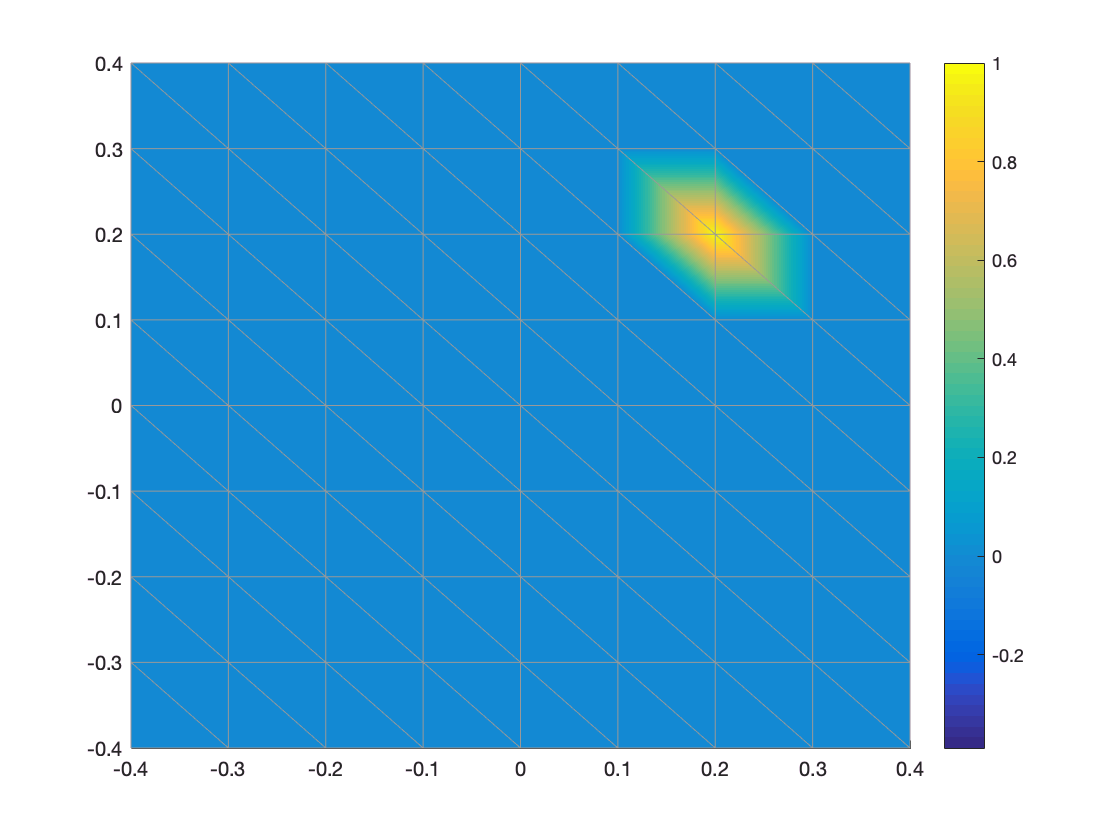

i = 41;
basei = zeros(nb,1);
basei(i) = 1;
C1 = alphas2V(basei);

V.plotu(C1)

In fact, if we stack all base functions into one matrix, it would be

alphas = eye(nb);
C = alphas2V(alphas);

## Observations

Now let's assume $g$ describes true states, but we don't know it yet.

We made some observations every $2\Delta t$, at positions $(-0.2, -0.2), (-0.2, 0), (-0.2, 0.2), (0, -0.2), (0, 0), (0, 0.2), (0.2, -0.2), (0.2, 0), (0.2, 0.2)$ and we have some error in our observations.

[X, Y] = meshgrid([-0.2 0 0.2], [-0.2 0 0.2]);
nobst = 15;        % how many times we make observations
nsensor = numel(X);   % number of sensors
noise = 0;
ndtobs = 1;     % observe every `ndtobs` timestep

data = zeros(nobst * nsensor, 1);
for i = 1:nobst
    data((nsensor*(i-1)+1):(nsensor*i)) = reshape(g(X,Y,dt*ndtobs*i), nsensor, 1) + randn(nsensor, 1)*noise;
end

In order to do data assimilation, we also need to define a function for numerical observations. To do that, we need an interpolation function in our finite element package that can evaluate a function given a vector $u$ and location $(x, y)$. This is not implemented in my MatFem. So for now I'll just hard code the observation in `observe` at the end of this file.

## Homogenize

Consider the homogenized Poisson system:


$$u_t-\Delta u = 0\quad \text{on }\Omega\\
u=0\quad\text{on }\partial\Omega\\
u=u_0\quad t=0$$


Because of the linearity of this system, if $u_1, u_2$ are two solutions to this system corresponding to initial conditions $u_{01}, u_{02}$, then for any $\alpha_1,\alpha_2\in R$, $\alpha_1u_1+\alpha_2u_2$ is a solution corresponding to initial condition $\alpha_1u_{01}+\alpha_2u_{02}$. 

Moreover, if $u^*$ is a solution to the inhomogeneous system with initial condition $u_0^*$, then $\sum_i\alpha_iu_i+u^*$ is a solution to the inhomogeneous system with initial condition $\sum_i\alpha_iu_{0i}+u_0^*$.

A solution to the homogenized system is written in function `Fh`. See the end of this file.

We randomly select an initial condition for inhomogeneous system

u0star = zeros(V.nb, 1);
u0star = bc.applyDir('d', @(x,y)g(x,y,0), u0star);

Note that a smooth $u_0^*$ is better. Here we just leave it as it is for simplicity.

If we observe this solution, we can get a set of data

inhodata = zeros(nobst * nsensor, 1);
ustar = u0star;
for i = 1:(nobst*ndtobs)
    t = i * dt;
    ustar = F(ustar, t); % solve for $\tilde{C_i^0}$ at time $t$.
    if mod(i, ndtobs) == 0
        inhodata((1+nsensor*(i/ndtobs-1)):(nsensor*i/ndtobs)) = observe(ustar);
    end
end

Subtracting real data by this one, we get the data that should be observed by homogeneous system.

homodata = data - inhodata;

## Solve for $\tilde C_i$

Now by using the homogeneous solver and the bases we introduced above, we can solve for $\tilde {C_i^0}$ and $\tilde{C_i}$.

numdata = zeros(nobst*nsensor, nb);

Ct = C;
for i = 1:(nobst*ndtobs)
    Ct = Fh(Ct);
    if mod(i, ndtobs) == 0
        numdata((1+nsensor*(i/ndtobs-1)):(nsensor*i/ndtobs), :) = observe(Ct);
    end
end

The $i^{\rm th}$ column of `numdata` corresponds to $\tilde{C_i}$.

## Solve for $u_0$

Now we are ready to solve for all $\alpha_i$. We expect `numdata * alphas = homodata`. So

alphas = numdata \ homodata;

The guess of our initial condition is then

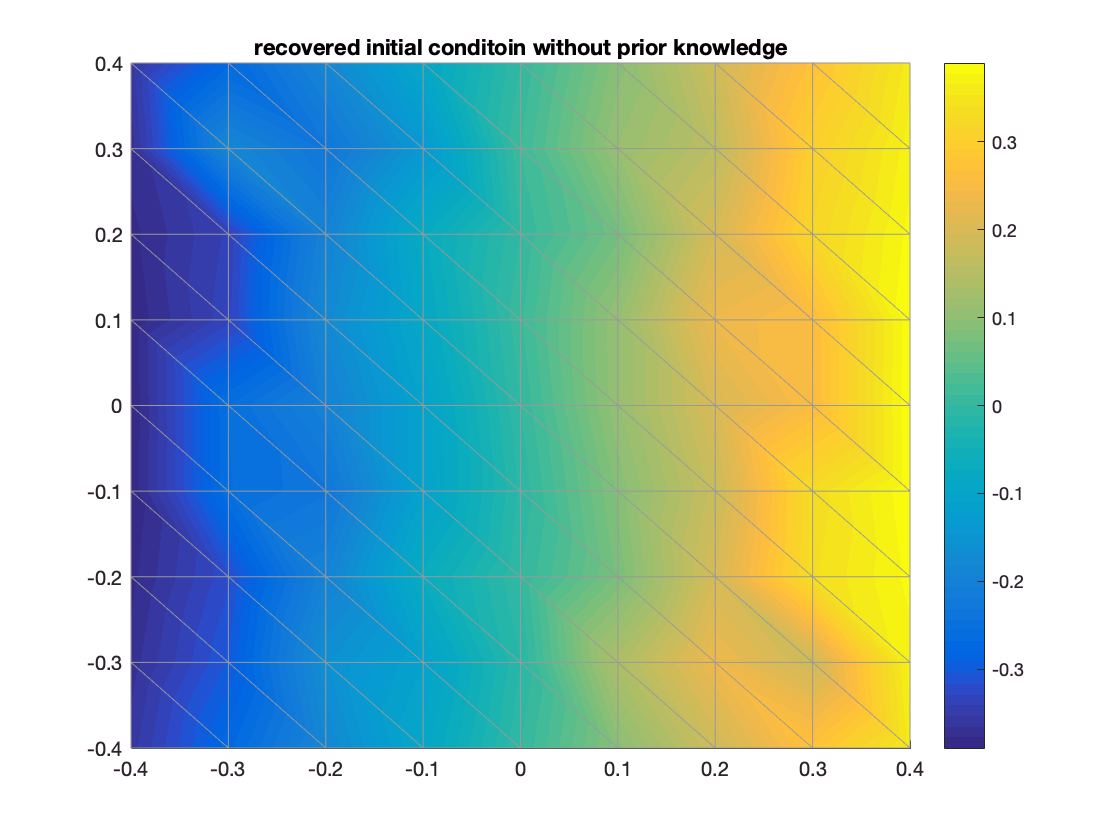

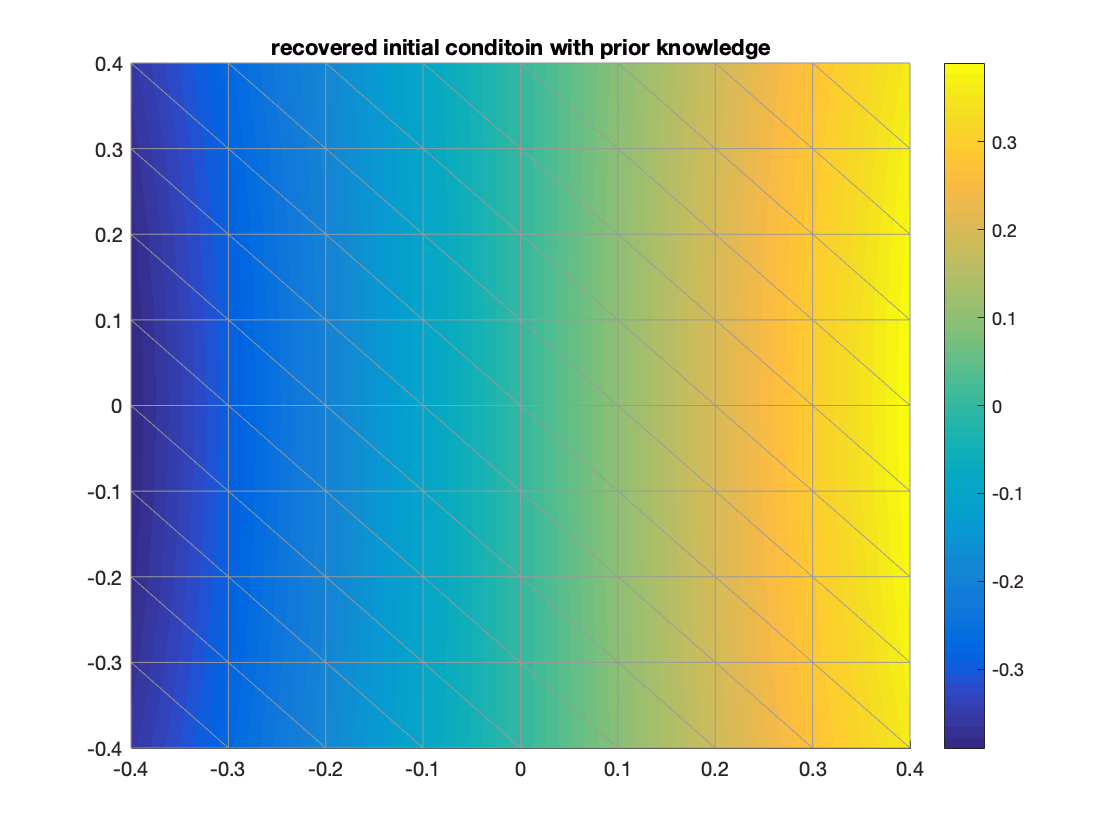

u0 = alphas2V(alphas) + u0star;

figure();
V.plotu(u0)
title('recovered initial conditoin without prior knowledge');
MatFem.errorNorm(V, u0, @(x,y)u_true(x,y,0), 'L2')

ans = 0.0145

## Solve for $u_0$ with prior $\beta$

If we have some prior knowledge $\beta=u_0$, given weight $\kappa=0.01$, then the least square solve becomes

beta  = V.project(@(x,y)u_true(x,y,0));
kappa = 0.01;

alphas = (numdata' * numdata + kappa * eye(nb)) \ (numdata' * homodata + kappa * V2alphas(beta));

u0 = alphas2V(alphas) + u0star;
figure();
V.plotu(u0)
title('recovered initial conditoin with prior knowledge');
MatFem.errorNorm(V, u0, @(x,y)u_true(x,y,0), 'L2')

ans = 3.5642e-04

## Functions

function u = F(u_old, t)
    % Solve the poisson system for 1 timestep.
    import MatFem.assemble
    global V bc Auv f g A dt
    
    b = dt * assemble(V, [0 0], @(x,y)f(x,y,t)); % ∆t * integrate(f*v)
    b = b + Auv * u_old; % Auv * u_old gives integrate(u_old*v)
    b = bc.applyDir('d', @(x,y)g(x,y,t), b); % apply boundary condition
    u = A \ b;
end

function u = Fh(u_old)
    % Solve the homogenized poisson system for 1 timestep.
    import MatFem.assemble
    global bc Auv A
    
    b = Auv * u_old;
    b = bc.applyDir('d', 0, b);
    u = A \ b;
end

function v = alphas2V(alphas)
    % Map a vector of alphas to a function with
    %    v = \sum_i alpha_i \phi_i
    % where \phi_i is one basis of the functionspace V.
    %
    % This function is vectorized. `alphas` can be a 2D array
    % with each column represent a vector of alphas.
    global bases
    v = zeros(size(bases, 1), size(alphas, 2));
    v(bases,:) = alphas;
end

function alphas = V2alphas(v)
    % Map a vector in our function space to alphas.
    % I.e., remove all Dirichlet boundaries.
    global bases
    alphas = v(bases,:);
end

function data = observe(v)
    % Observe a state v in function space V.
    % Corresponds to sensors at locations:
    %     [-0.2 0 0.2] x [-0.2 0 0.2] (Cartesian product)
    % Vectorized so that alphas can be a row of vector of alphas.
    pos = [9 11 13 23 25 27 37 39 41]; % You can use the codes in section *Bases* to examine these indices
    alphas = V2alphas(v);
    data = alphas(pos, :);
end